## Codigo (3,1) sobre canal BSC

Se codifica cada bit repitiendolo 3 veces `(0->000, 1->111), se simula un canal binario simetrico (BSC) que invierte bits con probabilidad p, y se decodifica por mayoria. Se compara la BER con y sin codificacion.`

clear; clc; close all;

N = 100000;              % cantidad de bits de informacion a simular
p_vec = 0.01:0.02:0.45;  % barrido de probabilidad de error del canal (BSC)

BER_sin_codificar = zeros(size(p_vec));
BER_codificado     = zeros(size(p_vec));

- Simula un canal **BSC** con probabilidad de error `p.`

- Compara dos casos: transmitir bits pelados vs. transmitir el código de repetición **(3,1)** : cada bit se manda 3 veces y se decodifica **por mayoría** (si 2 de 3 dan 1, se decide 1).

for k = 1:length(p_vec)
    p = p_vec(k);

    % --- Bits de informacion ---
    bits = randi([0 1], 1, N);

    % ===== CASO SIN CODIFICAR =====
    % El canal invierte cada bit con probabilidad p
    errores = rand(1, N) < p;
    bits_rx_sin_cod = xor(bits, errores);
    BER_sin_codificar(k) = sum(bits_rx_sin_cod ~= bits) / N;

    % ===== CASO CODIFICADO (repeticion 3,1) =====
    % Codificar: cada bit se repite 3 veces
    cod = repelem(bits, 3);            % ej: 1 -> [1 1 1]

    % Canal BSC sobre la secuencia codificada (3*N bits)
    errores_cod = rand(1, 3*N) < p;
    rx = xor(cod, errores_cod);

    % Decodificar por mayoria (cada grupo de 3 bits recibidos)
    rx_reshape = reshape(rx, 3, N);        % columnas = grupos de 3
    suma = sum(rx_reshape, 1);             % cuenta de "unos" en cada grupo
    bits_decodificados = suma >= 2;        % mayoria (2 de 3 o mas -> 1)

    BER_codificado(k) = sum(bits_decodificados ~= bits) / N;
end

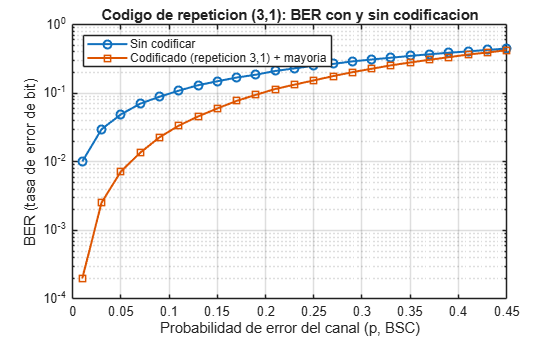

figure;
semilogy(p_vec, BER_sin_codificar, 'o-', 'LineWidth', 1.5); hold on;
semilogy(p_vec, BER_codificado, 's-', 'LineWidth', 1.5);
grid on;
xlabel('Probabilidad de error del canal (p, BSC)');
ylabel('BER (tasa de error de bit)');
title('Codigo de repeticion (3,1): BER con y sin codificacion');
legend('Sin codificar', 'Codificado (repeticion 3,1) + mayoria', 'Location', 'northwest');

## Efecto Entrelazado (Interleaving)

`Tenemos 6 bits de informacion, cada uno codificado con repeticion (3,1): bit -> 3 copias iguales (000 o 111). Eso arma una matriz de 6 filas (una por bit) x 3 columnas (una por copia).`

`El canal va a sufrir una ``RAFAGA``: varios simbolos SEGUIDOS se corrompen (por ejemplo, un rayon en un disco, o un desvanecimiento del canal).`

- `Si transmitimos "``por filas``" (mandamos las 3 copias de un bit, juntas, y recien despues las 3 copias del siguiente bit), la rafaga cae toda sobre las 3 copias de UN MISMO bit -> el codigo no tiene forma de arreglarlo, porque perdio TODA la informacion de ese bit.`

- `Si transmitimos "``por columnas``" (primero la copia 1 de los 6 bits, despues la copia 2 de los 6 bits, etc. = ENTRELAZADO), la misma rafaga queda repartida: cada bit pierde nada mas que 1 de sus 3 copias. Como el codigo de repeticion corrige 1 error de cada 3, el receptor arregla todo por mayoria.`

clear; clc;

bits = [1 0 1 1 0 0];         % 6 bits de informacion
M = length(bits);

% Matriz de codigo: fila = bit, columna = copia (1,2,3)
cod = repmat(bits', 1, 3);    % 6x3, cada fila repetida 3 veces

disp('--- Bits originales ---');

--- Bits originales ---


disp(bits);

     1     0     1     1     0     0



disp('--- Matriz codificada (filas=bits, columnas=copias) ---');

--- Matriz codificada (filas=bits, columnas=copias) ---


disp(cod);

     1     1     1
     0     0     0
     1     1     1
     1     1     1
     0     0     0
     0     0     0



L = 3;                  % longitud de la rafaga (en simbolos consecutivos)
pos_inicio = 4;         % en que posicion de la secuencia TRANSMITIDA arranca la rafaga

#### `CASO A: transmision SIN entrelazar (por filas)`

tx_sin_intercalar = reshape(cod', 1, []);   % orden: fila1(3 copias), fila2(3 copias), ...

rx_sin_intercalar = tx_sin_intercalar;
rx_sin_intercalar(pos_inicio:pos_inicio+L-1) = ~rx_sin_intercalar(pos_inicio:pos_inicio+L-1);

% Reconstruir matriz recibida y decodificar por mayoria
matriz_rx_A = reshape(rx_sin_intercalar, 3, M)';
bits_dec_A = sum(matriz_rx_A, 2) >= 2;

#### `CASO B: transmision CON entrelazado (por columnas)`

tx_intercalado = reshape(cod, 1, []);       % orden: columna1 (6 bits), columna2 (6 bits), columna3 (6 bits)

rx_intercalado = tx_intercalado;
rx_intercalado(pos_inicio:pos_inicio+L-1) = ~rx_intercalado(pos_inicio:pos_inicio+L-1);

% Reconstruir matriz recibida (deshacer el entrelazado) y decodificar por mayoria
matriz_rx_B = reshape(rx_intercalado, M, 3);
bits_dec_B = sum(matriz_rx_B, 2) >= 2;

fprintf('\n===== CASO A: SIN entrelazar (rafaga cae sobre un mismo bit) =====\n');


===== CASO A: SIN entrelazar (rafaga cae sobre un mismo bit) =====


disp('Secuencia transmitida:'); disp(tx_sin_intercalar);

Secuencia transmitida:
     1     1     1     0     0     0     1     1     1     1     1     1     0     0     0     0     0     0



disp('Secuencia recibida (con rafaga):'); disp(double(rx_sin_intercalar));

Secuencia recibida (con rafaga):
     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0



disp('Bits decodificados:'); disp(double(bits_dec_A)');

Bits decodificados:
     1     1     1     1     0     0



fprintf('Errores luego de decodificar: %d de %d bits\n', sum(bits_dec_A' ~= bits), M);

Errores luego de decodificar: 1 de 6 bits



fprintf('\n===== CASO B: CON entrelazado (rafaga se reparte entre bits) =====\n');


===== CASO B: CON entrelazado (rafaga se reparte entre bits) =====


disp('Secuencia transmitida:'); disp(tx_intercalado);

Secuencia transmitida:
     1     0     1     1     0     0     1     0     1     1     0     0     1     0     1     1     0     0



disp('Secuencia recibida (con rafaga):'); disp(double(rx_intercalado));

Secuencia recibida (con rafaga):
     1     0     1     0     1     1     1     0     1     1     0     0     1     0     1     1     0     0



disp('Bits decodificados:'); disp(double(bits_dec_B)');

Bits decodificados:
     1     0     1     1     0     0



fprintf('Errores luego de decodificar: %d de %d bits\n', sum(bits_dec_B' ~= bits), M);

Errores luego de decodificar: 0 de 6 bits
